% State equations
syms x1 x2 p1 p2 u;
Dx1 = x2;
Dx2 = -x2 + u;

% Cost function inside the integral
syms g;
g = 0.5*u^2;

% Hamiltonian
syms p1 p2 H;
H = g + p1*Dx1 + p2*Dx2;

% Costate equations
Dp1 = -diff(H,x1);
Dp2 = -diff(H,x2);

% solve for control u
du = diff(H,u);
sol_u = solve(du, u);

% Substitute u to state equations
Dx2 = subs(Dx2, u, sol_u);

% convert symbolic objects to strings for using ’dsolve’
eq1 = strcat("Dx1=",char(Dx1));
eq2 = strcat("Dx2=",char(Dx2));
eq3 = strcat("Dp1=",char(Dp1));
eq4 = strcat("Dp2=",char(Dp2));

% case a: (a) x1(0)=x2(0)=0; x1(2) = 5; x2(2) = 2;
conA1 = "x1(0) = 0";
conA2 = "x2(0) = 0";
conA3 = "x1(2) = 5";
conA4 = "x2(2) = 2";
sol_a = dsolve(eq1,eq2,eq3,eq4,conA1,conA2,conA3,conA4);

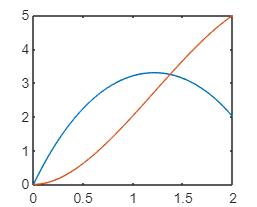

fplot(sol_a.x2,[0, 2]);
hold on;
fplot(sol_a.x1,[0, 2]);